##  Задание 1. Модальный регулятор. 

Начальные условия на задание:

A = [12, -1, 14; 
     6, 0, 6;
     -6, -2, -8]

A =     12    -1    14
     6     0     6
    -6    -2    -8


B = [11;
      7;
      -7]

B =     11
     7
    -7


Найти собственные числа матрицы A и определить управляемость каждого из них. Сделать вывод об управляемости и стабилизируемости системы.

U = ctrb(A, B)

U =     11    27   -36
     7    24    18
    -7   -24   -18


U = [B , A*B , A^2 * B]

U =     11    27   -36
     7    24    18
    -7   -24   -18


rank(U)

ans = 2

Проверка критерия Хаутуса:

eig(A)

ans =    3.0000 + 3.0000i
   3.0000 - 3.0000i
  -2.0000 + 0.0000i


l1 = 3 + 3j; l2 = 3 - 3j; l3 = -2;

vpa([A - eye(3).*l1 , B])

$$ans = \left(\begin{array}{cccc} 9.0-3.0\,\mathrm{i} & -1.0 & 14.0 & 11.0\\ 6.0 & -3.0-3.0\,\mathrm{i} & 6.0 & 7.0\\ -6.0 & -2.0 & -11.0-3.0\,\mathrm{i} & -7.0 \end{array}\right)$$

vpa([A - eye(3).*l2 , B])

$$ans = \left(\begin{array}{cccc} 9.0+3.0\,\mathrm{i} & -1.0 & 14.0 & 11.0\\ 6.0 & -3.0+3.0\,\mathrm{i} & 6.0 & 7.0\\ -6.0 & -2.0 & -11.0+3.0\,\mathrm{i} & -7.0 \end{array}\right)$$

vpa([A - eye(3).*l3 , B])

$$ans = \left(\begin{array}{cccc} 14.0 & -1.0 & 14.0 & 11.0\\ 6.0 & 2.0 & 6.0 & 7.0\\ -6.0 & -2.0 & -6.0 & -7.0 \end{array}\right)$$


rank([A - eye(3).*l1 , B])

ans = 3

rank([A - eye(3).*l2 , B])

ans = 3

rank([A - eye(3).*l3 , B])

ans = 2

**A --> Стабилизируема, но не управляема**

Рассмотреть предложенные в соответствии с вашем вариантом  желаемые спектры замкнутой системы (A+BK) и определить, какие из них дости жимы, а какие нет. Обосновать выбор.

Не управляемые собственные числа нам не достичь, поэтому они должны в наборе остаться...

В моём случае lambda = -2 неуправляемо, значит оно должно быть в наборе...

lambdas=[-1,-1,-1]; %  НЕТ
lambdas=[-2,-2,-2]; % ДА
lambdas=[-1,-10,-100]; % НЕТ
lambdas=[-2,-20,-200]; % ДА
lambdas=[-1,-1-3i, -1+3i]; % НЕТ
lambdas=[-2,-2-6i,-2+6i]; % ДА


Для каждого спектра...

lambdas=[-2,-2,-2];

[P,Aj] = jordan(A)

P =   -1.0000 + 0.0000i  -1.5000 + 0.5000i  -1.5000 - 0.5000i
   0.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i
   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i


Aj =   -2.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   3.0000 - 3.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   3.0000 + 3.0000i


[P2, Aj2] = cdf2rdf(P,Aj)

P2 =    -1.0000   -2.1213    0.7071
         0   -1.4142         0
    1.0000    1.4142         0


Aj2 =     -2     0     0
     0     3    -3
     0     3     3



P1(:,1)=real(P(:,1)); 
P1(:,2)=imag(P(:,2)); 
P1(:,3)=real(P(:,3)); 
 
Aj1=P1^-1*A*P1 

Aj1 =     -2     0     0
     0     3     3
     0    -3     3



A_reduced = inv(P1) * A * P1 ; A_reduced(1,:)=[]; A_reduced(:,1)=[]

A_reduced =      3     3
    -3     3


B_reduced = inv(P1) * B ; B_reduced(1,:) = []

B_reduced =      1
    -7



G = [-2 1;
      0 -2];
Y = [1 0]

Y =      1     0


P = sylvester(A_reduced, -G, B_reduced*Y);
K = -Y*inv(P)

K =     0.5467    1.5067


eig(A_reduced + B_reduced * K)

ans =    -2.0000
   -2.0000



K_pad = [0 K]

K_pad =          0    0.5467    1.5067


K = K_pad * inv(P1)

K =     1.0933   -2.0533    1.0933


eig(A + B * K)

ans =   -2.0000 + 0.0000i
  -2.0000 - 0.0000i
  -2.0000 + 0.0000i



%%%%%%%%%%%%%%%% - nice
G = [-2    1  0;
      0   -2  1;
      0    0 -2]

G =     -2     1     0
     0    -2     1
     0     0    -2


Y = [1, 1, 1]

Y =      1     1     1


cvx_begin sdp
variable P(3,3)
A*P - P*G == B*Y;
cvx_end

Homogeneous problem detected; solution determined analytically.
Status: Solved
Optimal value (cvx_optval): +0
 


K = -Y*pinv(P)

K =     1.0933   -2.0826    1.0641


eig(A+B*K)

ans =    -2.0000
   -2.0000
   -2.0000


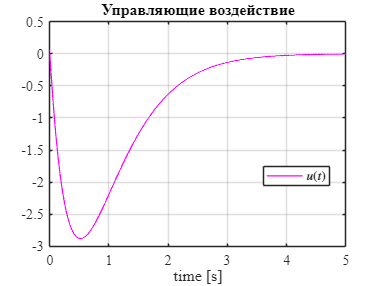

%%%%%%%%%%%%%%%%
x0 = [1, 1, 1]';
D = 0;
C = [1, 1, 1];
L = [0 0 0];

simTimeStart = 0;
simTimeEnd = 5;
step = 0.0001;
time = (simTimeStart:step:simTimeEnd)';
% u = zeros(1, length(time));
data.time= time;
modelName = 'model_controller'; 
load_system(modelName);
out = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));

time = out.y_plant.Time;                
x_plant = out.x_plant.Data;
u = out.u.Data;

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, u, 'magenta', 'LineWidth', 1.0); 
grid on;
xlabel('time [s]');                                   
legend('$u(t)$', ...
        'Location', 'best', 'Interpreter', 'latex');
title('Управляющие воздействие')
save_file("ctrl_u1");

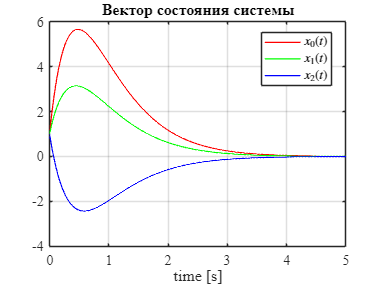


h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, x_plant(:,1), 'r', 'LineWidth', 1.0); hold on
plot(time, x_plant(:,2), 'g', 'LineWidth', 1.0); 
plot(time, x_plant(:,3), 'b', 'LineWidth', 1.0); 
grid on;
xlabel('time [s]');                                   
legend('$x_0(t)$','$x_1(t)$','$x_2(t)$', ...
        'Location', 'best', 'Interpreter', 'latex');
title('Вектор состояния системы');
save_file("ctrl_x1");

lambdas=[-2,-20,-200];
G = diag(lambdas)

G =     -2     0     0
     0   -20     0
     0     0  -200


Y = [1, 1, 2]

Y =      1     1     2



%%%%%%%%%%%%%%%% - nice
cvx_begin sdp
variable P(3,3)
A*P - P*G == B*Y;
cvx_end

Homogeneous problem detected; solution determined analytically.
Status: Solved
Optimal value (cvx_optval): +0
 


K = -Y*pinv(P)

K =   425.8933 -387.0283  314.5183


eig(A+B*K)

ans =  -200.0000
  -20.0000
   -2.0000


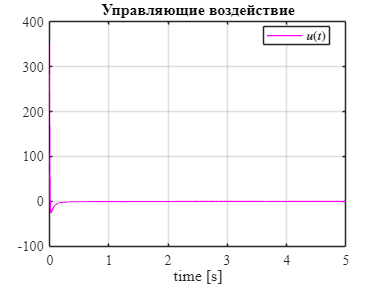

%%%%%%%%%%%%%%%%

x0 = [1, 1, 1]';
D = 0;
C = [1, 1, 1];
L = [0 0 0];

simTimeStart = 0;
simTimeEnd = 5;
step = 0.0001;
time = (simTimeStart:step:simTimeEnd)';
% u = zeros(1, length(time));
data.time= time;
modelName = 'model_controller'; 
load_system(modelName);
out = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));

time = out.y_plant.Time;                
x_plant = out.x_plant.Data;
u = out.u.Data;

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, u, 'magenta', 'LineWidth', 1.0); 
grid on;
xlabel('time [s]');                                   
legend('$u(t)$', ...
        'Location', 'best', 'Interpreter', 'latex');
title('Управляющие воздействие')
save_file("ctrl_u2");

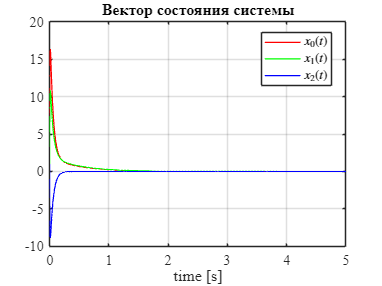


h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, x_plant(:,1), 'r', 'LineWidth', 1.0); hold on
plot(time, x_plant(:,2), 'g', 'LineWidth', 1.0); 
plot(time, x_plant(:,3), 'b', 'LineWidth', 1.0); 
grid on;
xlabel('time [s]');                                   
legend('$x_0(t)$','$x_1(t)$','$x_2(t)$', ...
        'Location', 'best', 'Interpreter', 'latex');
title('Вектор состояния системы');
save_file("ctrl_x2");

lambdas=[-2,-2-6i,-2+6i];

G = [-2    0  0;
      0   -2  6;
      0    -6 -2]

G =     -2     0     0
     0    -2     6
     0    -6    -2


eig(G)

ans =   -2.0000 + 6.0000i
  -2.0000 - 6.0000i
  -2.0000 + 0.0000i


Y = [1, 1, 0]  % not working with Y = [1, 1, 2]

Y =      1     1     0



%%%%%%%%%%%%%%%% - nice
cvx_begin sdp
variable P(3,3)
A*P - P*G == B*Y;
cvx_end

 
Calling SDPT3 4.0: 7 variables, 6 equality constraints
------------------------------------------------------------

 num. of constraints =  7
 dim. of linear var  =  1
 dim. of free   var  =  7 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|1.1e+00|4.2e+02|4.5e+04| 0.000000e+00  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.988|1.7e-07|5.3e+00|1.2e+02| 0.000000e+00 -7.983348e+00| 0:0:01| chol  1  1 
 2|1.000|0.989|2.4e-08|6.8e-02|4.5e-01| 0.000000e+00 -8.443976e-02| 0:0:01| chol  1  1 
 3|1.000|0.989|3.8e-09|1.7e-03|4.1e-03| 0.000000e+00 -3.419334e-04| 0:0:01| chol  1  1 
 4|1.000|0.989|

K = -Y*pinv(P)

K =     4.4533   -5.0983    3.3283


eig(A+B*K)

ans =   -2.0000 + 6.0000i
  -2.0000 - 6.0000i
  -2.0000 + 0.0000i


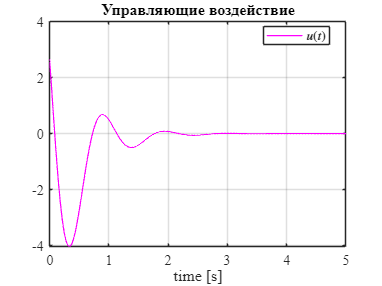

%%%%%%%%%%%%%%%%
x0 = [1, 1, 1]';
D = 0;
C = [1, 1, 1];
L = [0 0 0];

simTimeStart = 0;
simTimeEnd = 5;
step = 0.0001;
time = (simTimeStart:step:simTimeEnd)';
% u = zeros(1, length(time));
data.time= time;
modelName = 'model_controller'; 
load_system(modelName);
out = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));

time = out.y_plant.Time;                
x_plant = out.x_plant.Data;
u = out.u.Data;

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, u, 'magenta', 'LineWidth', 1.0); 
grid on;
xlabel('time [s]');                                   
legend('$u(t)$', ...
        'Location', 'best', 'Interpreter', 'latex');
title('Управляющие воздействие')
save_file("ctrl_u3");

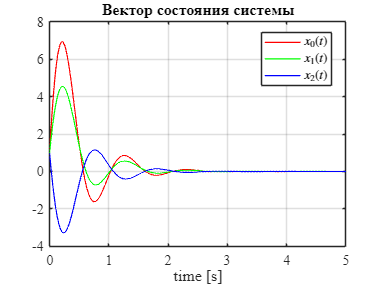


h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, x_plant(:,1), 'r', 'LineWidth', 1.0); hold on
plot(time, x_plant(:,2), 'g', 'LineWidth', 1.0); 
plot(time, x_plant(:,3), 'b', 'LineWidth', 1.0); 
grid on;
xlabel('time [s]');                                   
legend('$x_0(t)$','$x_1(t)$','$x_2(t)$', ...
        'Location', 'best', 'Interpreter', 'latex');
title('Вектор состояния системы');
save_file("ctrl_x3");

**Функция, чтобы сохранить картинку в папку**

function save_file(name)
    path = 'D:\Math\control_theory\control_theory_labs\lab8\latex8\images';
    fullpath = fullfile(path, name);
    saveas(gcf, fullpath, 'png');

end